dataset = load('../main_dataset.mat');
dataset = dataset.dataset;


dataset_size = size(dataset);
ref_seq = dataset(1,2);
ref_seq_size = size(ref_seq{1},2);
other_seq = dataset(2:dataset_size(1),:);

result3(1:4,1:4)=0;
ge=[{'T'},{'C'},{'A'},{'G'}];

for i=1:dataset_size-1
    i
    data_row = other_seq(i,2);
    other_seq_size = size(data_row{1},2);
    it_len = min(ref_seq_size,other_seq_size);
    for j=1:it_len
        if(data_row{1}(j) ~= ref_seq{1}(j))
            id1=find(strcmp(ge,ref_seq{1}(j)));
            id2=find(strcmp(ge,data_row{1}(j)));
            result3(id1,id2)=result3(id1,id2) + 1;
        end
    end
end


save('../neucliotide_mutation.mat','result3');

% result3 = load('../neucliotide_mutation.mat');
% result3 = result3.result3
dataset = dataset.dataset;

dataset = 522×7 string array
    "NC_063383"    "ATTTTACTATTTTATTTAGTGTCTAGAAAAAAATGTGTGACCCACGACCGTAGGAAACTCTAGAGGGTAAGAAAAATCAATCGTTTATAGAGACCATCAGAAAGAGGTTTAATATTTTTGTGAGACCTATCGAAGAGAGAAAGGATAAAAACTTTTTACGACTCCATCAGAAAGAGGTTTAATATTTTTGTGAGACCCATCGAAGAGAGAAAGAGATGGTTAGTCAAGATATTTTTCTTAGTACAAAAGTCAATGTTTTAAAATATATGGACGAGAATTAATTTGTCTGTATAAAAACTTGTGTGAAATTATGTACTAGAGAAAAAACGTGAGCAGTGTCCCCTACATGGATTTTACAGATCATTTATATTCCAAAAATATTAACTATATACGTTTATTATATGATGTTAACGTGTAAATTATAAACATTATTTTATGATGCAATTGTCTGACAACCTAGATTGGTATAAGGATGTTGATAAGCTCTACGAGAATATATTGTTGGACGTTATCGTTTACGAAATAGTTGAGACATCAGAAAGAGGTTTAATATTTTTGTGAGACCATCGAAGAGAGAAAGAGAATAAAAATATTTTTTTTTTTTTTTTTGTAAAACTTTTTTATGAGACCAAGAGAATACGAATAGTGATCATATCGTATCACATATTGAAACAGAAAGAAGAAGTAACGAGAGGTAACTTTTTGTGAATGTAGTTAAATATTTTTGTTTTGCAAACCGGAATATAGTGCCCGGTCTTTTTTAATTCGTGGTGCGGTGTCTGAATCGTTCGATTAACCCAACTCATCCATTTTCAGATGAATAGAGTTATCGATTCAGACACATGCTTTGAGTTTTGTTGAATCGATGAGTGAAGTATCATCGGTTGCACCTTCAGATGCCGATCCGTCGACATACTTGAATCCATCCTTGACTTCAAGTTCAGATGATTC

dataset_size = size(dataset);
ref_seq = dataset(1,2);
ref_seq_size = size(ref_seq{1},2);

rrf=(result3/(ref_seq_size*dataset_size(1)))*100

rrf =          0    5.3256   10.7468    5.2200
    5.4134         0    5.2847    2.6184
   10.6742    5.2828         0    5.4377
    5.3318    2.5749    5.3748         0


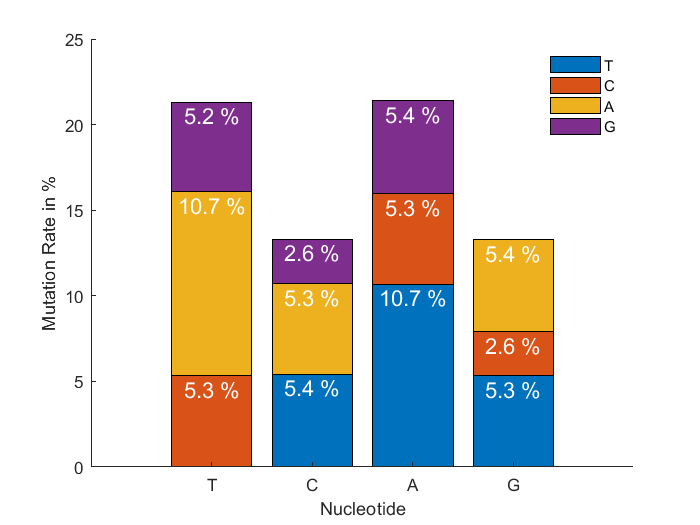

figure;bar(rrf,'stacked','DisplayName','result')
legend({'T','C','A','G'},'box','off');
clear xticklabels;
xticklabels({'T','C','A','G'});
ylabel('Mutation Rate in %')
xlabel('Nucleotide')
prediteddata=rrf;
for i=1:size(prediteddata,1)
    for j=1:size(prediteddata,2)
        if prediteddata(i,j)>0
        labels_stacked=num2str(prediteddata(i,j),'%.1f %%');
        hText = text(i, sum(prediteddata(i,1:j),2), labels_stacked);
        set(hText, 'VerticalAlignment','top', 'HorizontalAlignment', 'center','FontSize',13, 'Color','w');
        end
    end
end
box off;

% After Prediction from Python Print the Graph

rrf =   [[0, 3.93558359, 8.03419113, 3.90576124],
        [3.88959026,0, 1.90581965, 3.98026228],
        [3.94828558, 8.05398655,0, 3.89410043],
        [3.94476604, 1.93719852, 3.9899199,0 ]]

rrf =          0    3.9356    8.0342    3.9058
    3.8896         0    1.9058    3.9803
    3.9483    8.0540         0    3.8941
    3.9448    1.9372    3.9899         0



    
gru = [[0, 3.81861901, 7.86984444, 3.83200121],
        [3.78560877,0, 1.85787201, 3.88259172],
        [3.81825399, 7.84054661,0, 3.79077339],
        [3.81532812, 1.87345755, 3.86418748,0]]

gru =          0    3.8186    7.8698    3.8320
    3.7856         0    1.8579    3.8826
    3.8183    7.8405         0    3.7908
    3.8153    1.8735    3.8642         0


rrf = gru

rrf =          0    3.8186    7.8698    3.8320
    3.7856         0    1.8579    3.8826
    3.8183    7.8405         0    3.7908
    3.8153    1.8735    3.8642         0


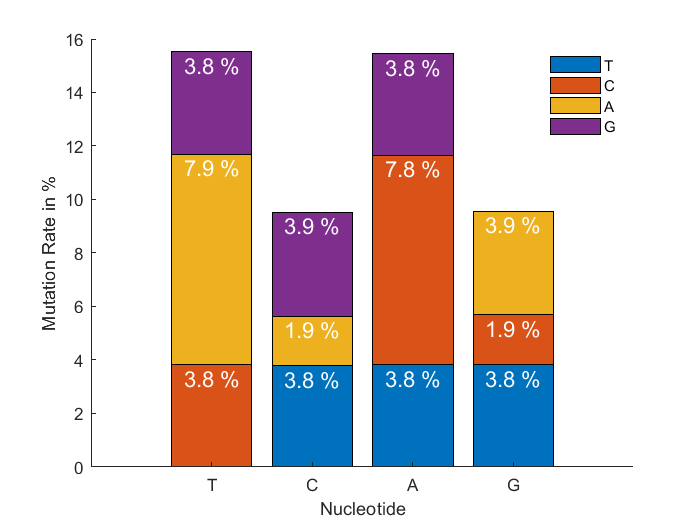

figure;bar(rrf,'stacked','DisplayName','result')
legend({'T','C','A','G'},'box','off');
clear xticklabels;
xticklabels({'T','C','A','G'});
ylabel('Mutation Rate in %')
xlabel('Nucleotide')
prediteddata=rrf;
for i=1:size(prediteddata,1)
    for j=1:size(prediteddata,2)
        if prediteddata(i,j)>0
        labels_stacked=num2str(prediteddata(i,j),'%.1f %%');
        hText = text(i, sum(prediteddata(i,1:j),2), labels_stacked);
        set(hText, 'VerticalAlignment','top', 'HorizontalAlignment', 'center','FontSize',13, 'Color','w');
        end
    end
end
box off;